# Setup YOLO Anchor Boxes and Architecture

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads a table containing filenames and corresponding bounding boxes.

rng(0)
load ../data/PetsImages/petGroundTruth.mat
imds = imageDatastore(petGroundTruth.imageFilename);
bxds = boxLabelDatastore(petGroundTruth(:, 2:end));
data = combine(imds, bxds);
scaledData = transform(data, @scaleGT);

## Task 1

YOLO detectors rely on anchor boxes to find bounding boxes. If you know the dimensions of your bounding boxes, you can pass those directly to your network architecture, but that isn't usually the case.

The `estimateAnchorBoxes` function will find suitable anchor boxes for your data set.

`bxs` `=` `estimateAnchorBoxes``(``data``,``numBxs``)`

The second input is the number of anchor boxes you want. A good starting point is the number of classes in your data set.

anchorBoxes = estimateAnchorBoxes(scaledData, 5)

anchorBoxes =    113    76
    57    39
   154   138
    97   131
    71    71


## Task 2

Now that you have anchor boxes suited for your data set, you can create the remaining inputs for the YOLO architecture.

net = resnet18

net =   DAGNetwork with properties:

         Layers: [71×1 nnet.cnn.layer.Layer]
    Connections: [78×2 table]
     InputNames: {'data'}
    OutputNames: {'ClassificationLayer_predictions'}


numClasses = 5;
imageSize = [224 224 3];

## Task 3

You'll use all the variables that you just created (plus a few more) to create your YOLO v2 architecture.

`layers` `=` `yolov2Layers``(``sz``,``n``,``box``,``net``,``...`

    `featureLayer``,``"ReorgLayerSource"``,``reorgLayer``)`

lgraph = yolov2Layers(imageSize, numClasses, anchorBoxes, net,...
    "res5b_relu", "ReorgLayerSource", "res3a_relu")

lgraph =   LayerGraph with properties:

     InputNames: {'data'}
    OutputNames: {'yolov2OutputLayer'}
         Layers: [78×1 nnet.cnn.layer.Layer]
    Connections: [86×2 table]


## Train the network

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* Bengal
* Chihuahua
* Pug
* Samoyed
* Sphynx

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |         3.84 |         14.8 |          0.0010 |
|       4 |          50 |       00:00:38 |         0.62 |          0.4 |          0.0010 |
|       7 |         100 |       00:01:15 |         0.37 |          0.1 |          0.0010 |
|      10 |         150 |       00:01:52 |         0.24 |      5.7e-02 |          0.0010 |
|      14 |       

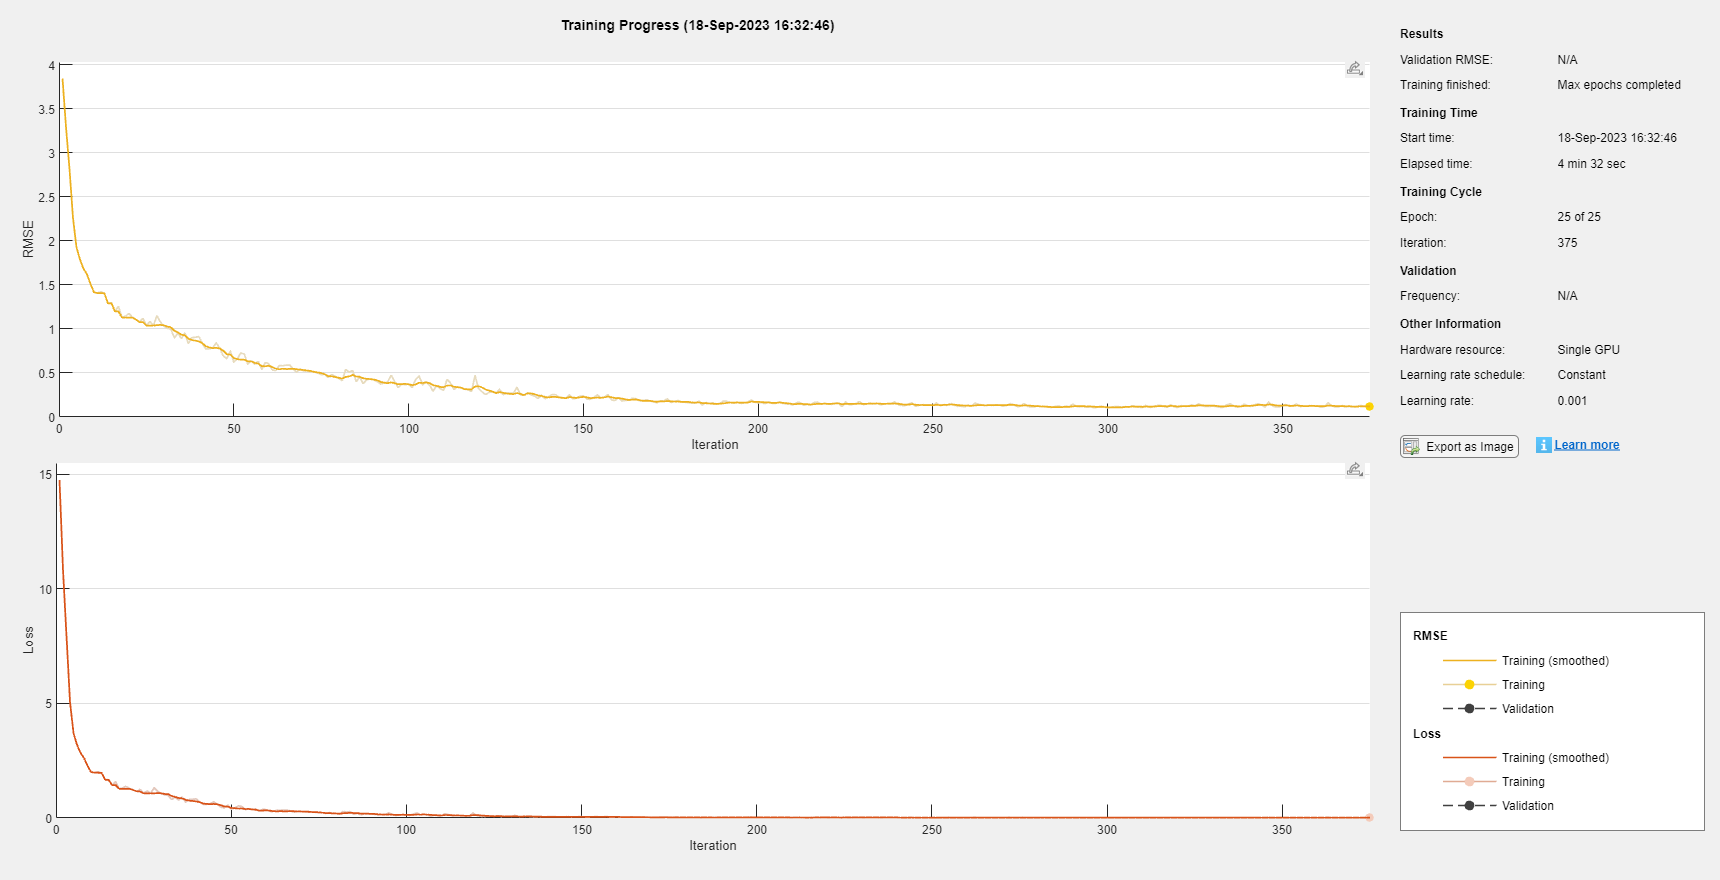

Detector training complete.
*************************************************************************



detector =   yolov2ObjectDetector with properties:

            ModelName: 'Bengal'
              Network: [1×1 DAGNetwork]
    TrainingImageSize: [224 224]
          AnchorBoxes: [5×2 double]
           ClassNames: [Bengal    Chihuahua    Pug    Samoyed    Sphynx]


options = trainingOptions(  "adam", ...
                            "MiniBatchSize", 32, ...
                            "InitialLearnRate", 0.001, ...
                            "MaxEpochs", 15, ...
                            "Shuffle", "every-epoch", ...
                            "Verbose", true, ...
                            "Plots", "training-progress");
detector = trainYOLOv2ObjectDetector(scaledData, lgraph, options)

`scaleGT` resizes images to `targetSize`. It also uses the same scale to resize the corresponding bounding boxes.

function data = scaleGT(data)  
    targetSize = [224 224];
    % data{1} is the image
    scale = targetSize./size(data{1}, [1 2]);
    data{1} = imresize(data{1}, targetSize);
    % data{2} is the bounding box
    data{2} = bboxresize(data{2}, scale);
end